# Calculate the Difference Between the Images

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

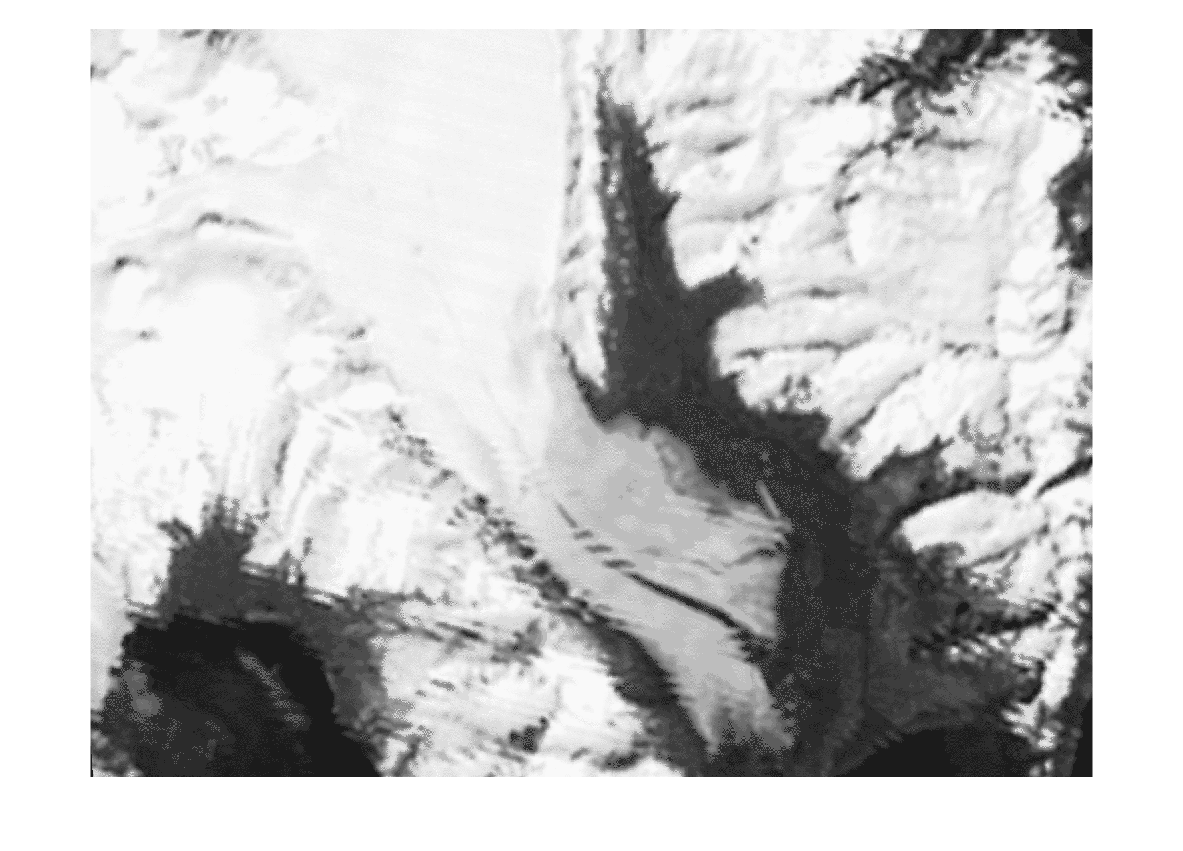

[crop1980, m80] = imread("./images/bearGlacier1980.png");
crop1980 = ind2gray(crop1980, m80);
imshow(crop1980)

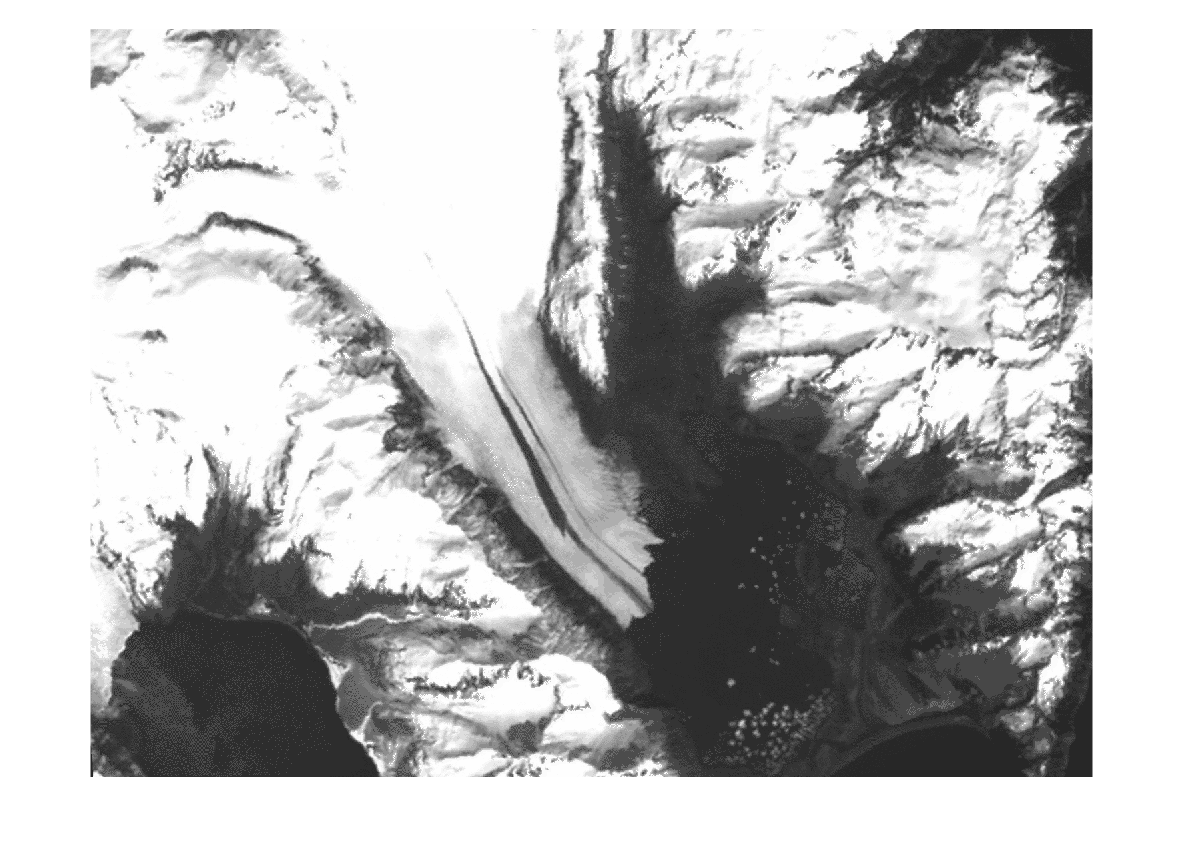


[crop2011, m11] = imread("./images/bearGlacier2011.png");
crop2011 = ind2gray(crop2011, m11);
imshow(crop2011)

## Task 1

diffIce = crop1980 - crop2011;

## Task 2

Pass `[]` as a second input to `imshow` to display an image using the full display range.

`imshow``(``I``,``[])`

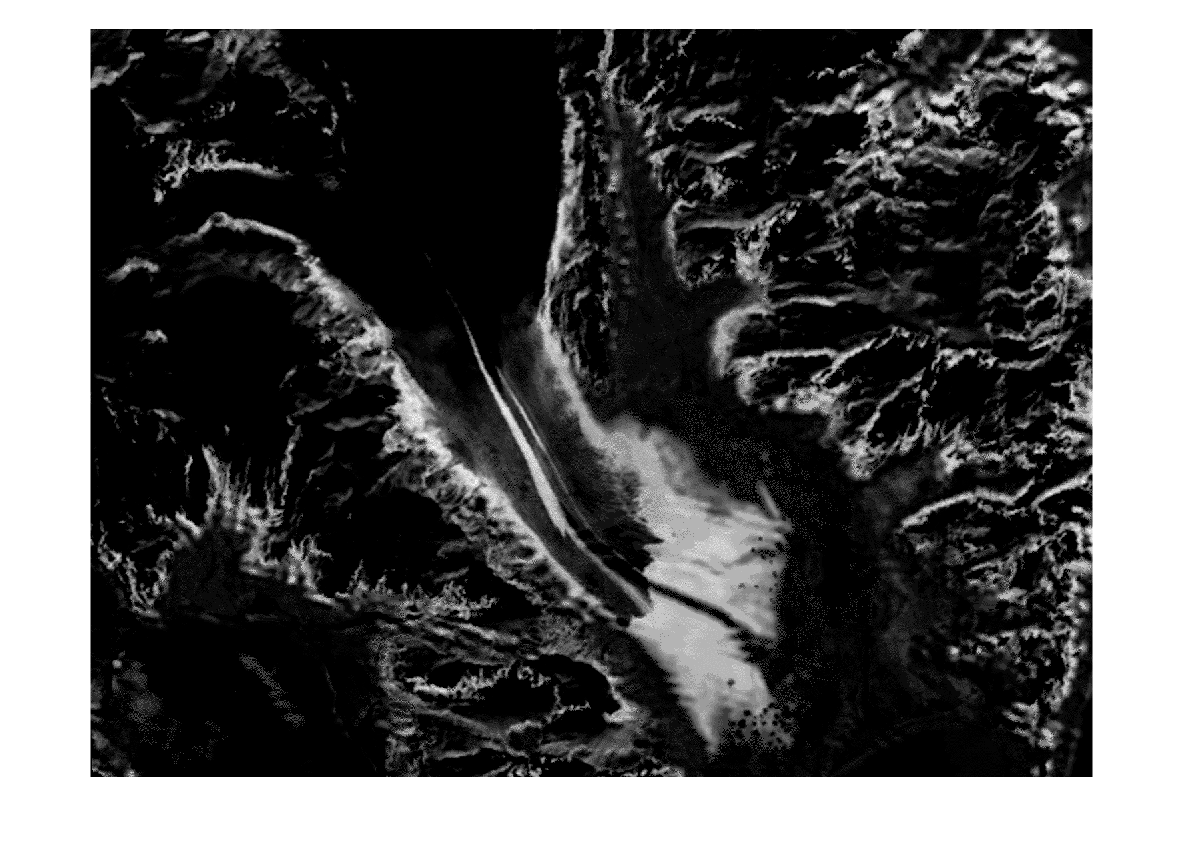

imshow(diffIce, [])

## Task 3

You can use `im2double` to convert an image to data type `double`. This also scales the image so that the values are between 0 and 1.

`imDbl` `=` `im2double``(``im``)``;`

crop1980 = im2double(crop1980);
crop2011 = im2double(crop2011);

## Task 4

diffIce = crop1980 - crop2011;

## Task 5

diffIce = rescale(diffIce);

## Task 6

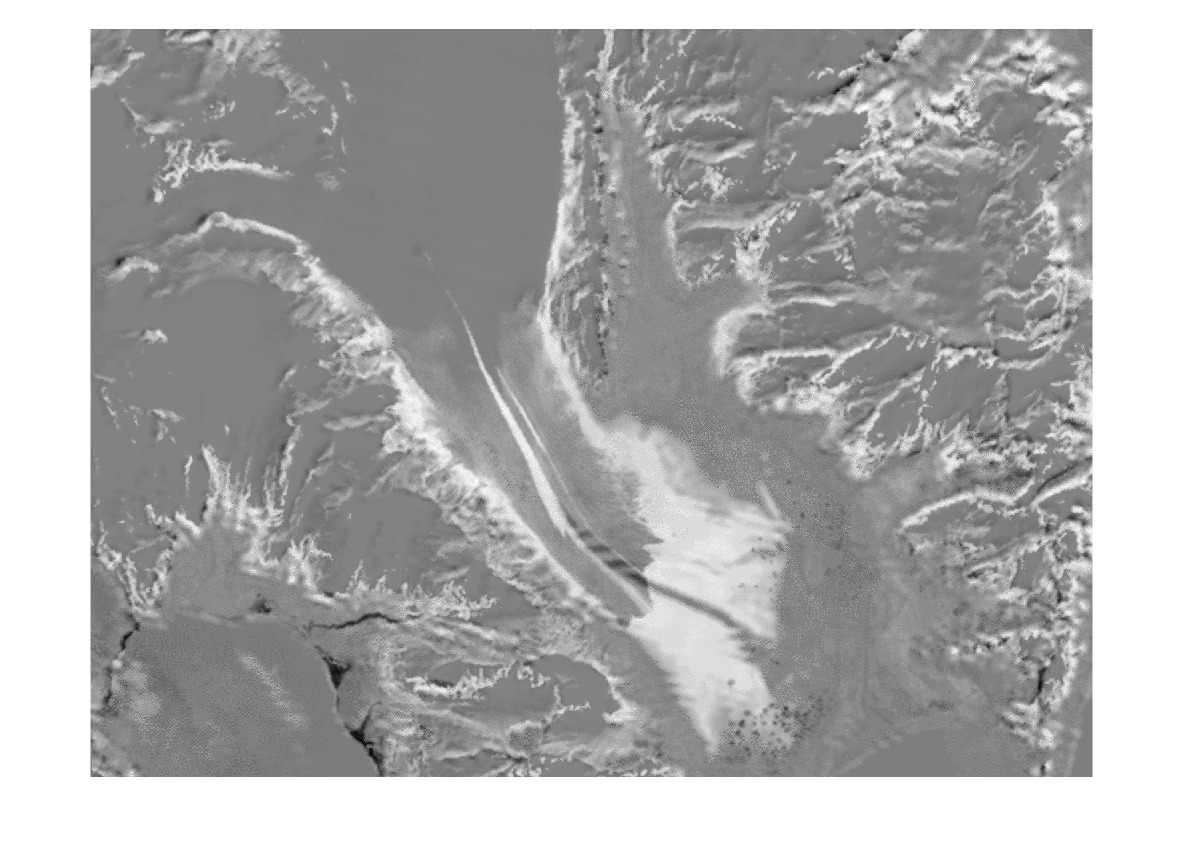

imshow(diffIce)

## Task 7

With this image, you can see where there was more ice in 2011 (dark areas) and more ice in 1980 (bright areas). The gray areas are where the images were about the same (both water, exposed land, or covered in ice).

Another way to create a difference visualization is with `imshowpair`.

`imshowpair``(``I1``,``I2``)`

Pixels where the first image is brighter are highlighted green. Pixels where the second input is brighter are highlighted magenta.

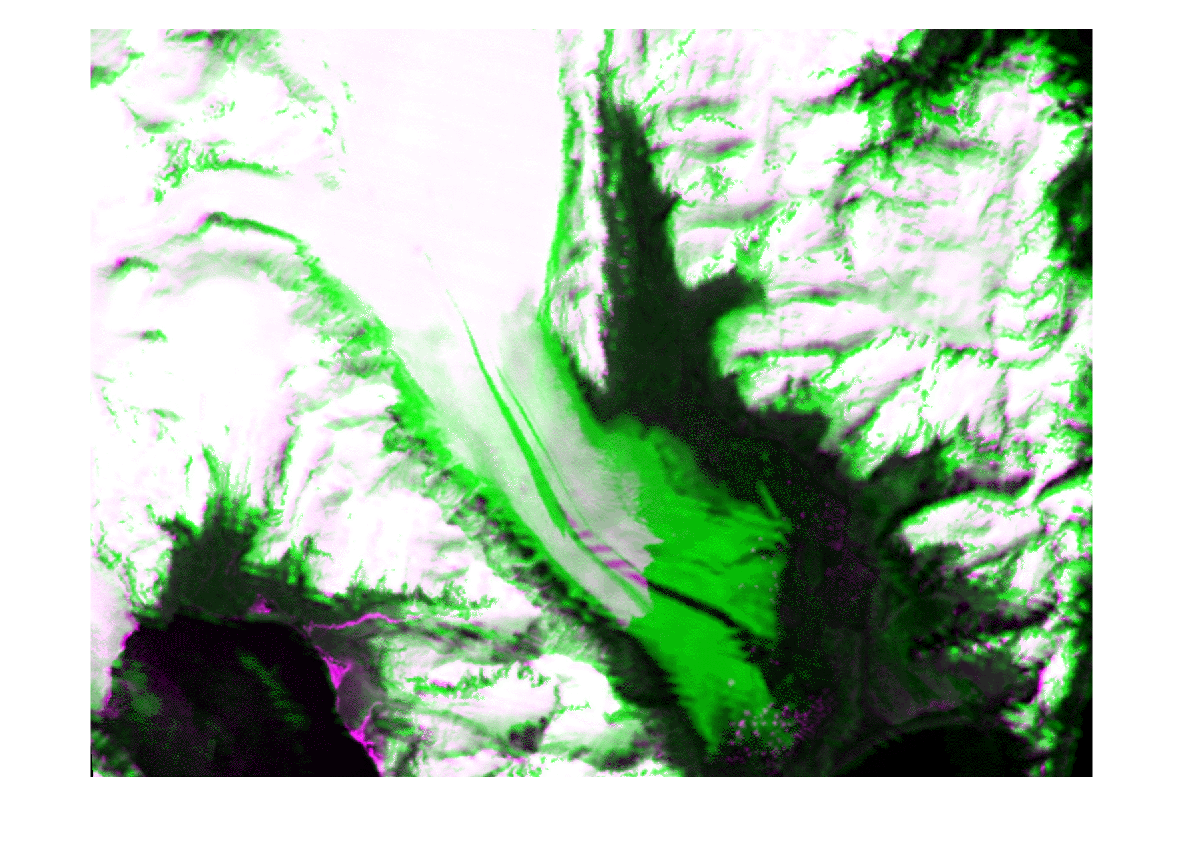

imshowpair(crop1980,crop2011)